# Algoritmo de Chirp Scaling ET-291

Alunos

DOUGLAS MASSAHIRO KOTSUBO

GUSTAVO HENRIQUE DE QUEIROZ STABILE

RODRIGO DE LIMA FLORINDO

## Aplicação do algoritmo de chirp scaling para alvos pontuais

Seguindo o mesmo procedimento realizado no relatório passado, iremos primeiro validar o uso do CSA para alvos pontuais, antes de aplica-lo em dados brutos reais.

% Inicialização do código limpando o workspace, a janela de 
% comandos e fechando todas a janelas abertas.
clear; clc; close all;

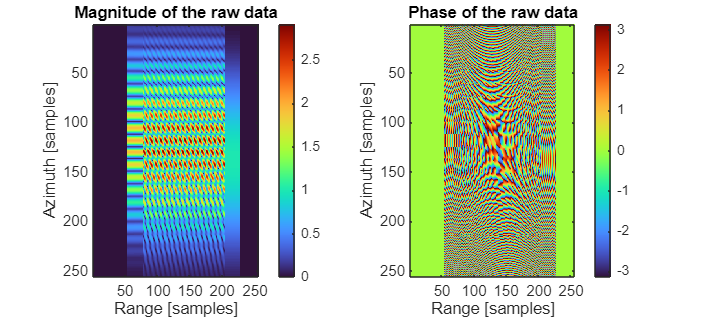

% Execução do código de geração de dados brutos sintéticos para alvos
% pontuais
run("Parametros_alvo_pontual.m");

% Exibição da Magnitude e da Fase dos dados brutos gerados
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(abs(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Magnitude of the raw data')
subplot(1,2,2);
imagesc(angle(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Phase of the raw data');

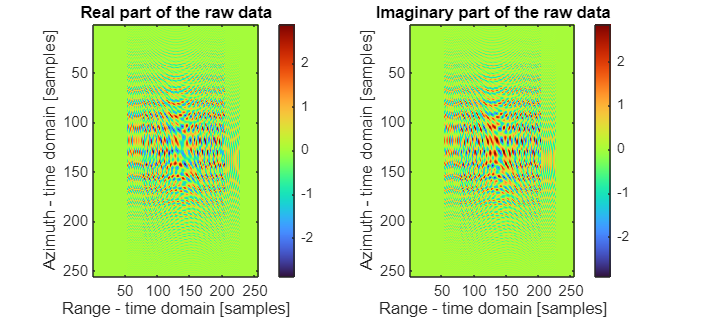


% Exibição das partes reais e imaginárias dos dados brutos sintéticos
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(real(s0_upchirp));
colorbar;
colormap('turbo');
xlabel('Range - time domain [samples]');
ylabel('Azimuth - time domain [samples]');
title('Real part of the raw data') 
subplot(1,2,2);
imagesc(imag(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range - time domain [samples]');
ylabel('Azimuth - time domain [samples]');
title('Imaginary part of the raw data');

Conforme Apresentado em [1], O diagrama de blocos de alto nível do Chirp Scaling Algorithm (CSA) é o seguinte:

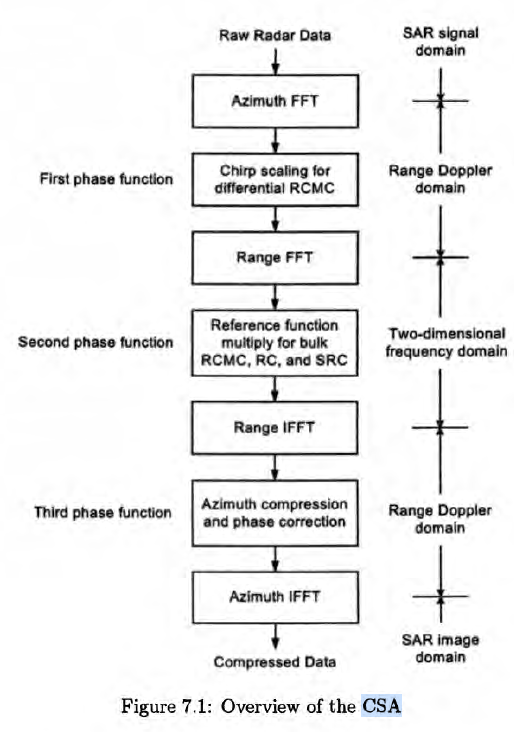

Portanto, é aplicado primeiramente uma FFT em azimute, transformando os dados brutos no domínio do tempo bidimensional para o domínio range-Doppler:

range_Doppler_data = zeros(Naz,Nrg);
for i = 1:Nrg
    range_Doppler_data(:,i) = fftshift(fft(s0_upchirp(:,i)));
end

Em seguida, é aplicado o Chirp Scaling para correção fina (diferencial) da migração das células em range (RCMC). A forma da função de escalonamento é dada pela equação 7.30 de [1]:


$$s_{\textrm{sc}} \left(\tau^{\prime } ,f_{\eta } \right)=\exp \left\lbrace \left.j\pi \;K_m \left\lbrack \frac{\;D\left(f_{\eta_{\textrm{ref}} } \;,V_{r_{\textrm{ref}} } \right)}{D\left(f_{\eta \;} \;,V_{r_{\textrm{ref}} } \right)}-1\right\rbrack {\left(\tau^{\prime } \right)}^2 \right)\right\rbrace$$


em que $\tau^{\prime }$ indica o tempo em range, $f_{\eta \;}$denota a frequência em azimute (frequência Doppler), 


$$K_m =\frac{K_r }{1-K_r \frac{{\textrm{cR}}_0 f_{\eta }^2 }{2V_r^2 f_0^3 D^3 \left(f_{\eta } ,V_r \right)}}\;\left(7\ldotp 18\;\textrm{de}\;\left\lbrack 1\right\rbrack \right)$$


representa a taxa FM modificada, que varia em função do parâmetro de migração em range dado por

$D\left(f_{\eta \;} \;,V_r \right)=\sqrt{1-\frac{c^2 f_{\eta }^2 }{4V_r^2 f_0^2 }}\;\left(7\ldotp 17\;\textrm{de}\;\left\lbrack 1\right\rbrack \right)$.

Ainda mais, $R_0$ denota o range mais próximo da aquisição da imagem, que pode ser considerado como o range na centróide de shift de frequência Doppler $f_0$ simboliza a banda de frequência da portadora e $V_r$ indica a velocidade efetiva do radar, a qual é considerada invariante no tempo.

com isso, pode-se usar as funções contidas no final deste documento para obter a função de escalonamento:

% Neste caso, foi assumido que a frequência de referência é igual à
% frequência da centróide Doppler.
f_eta_c = get_f_eta_c(Vr,lambda,R0,eta_c);
freq_ref_azimuth = f_eta_c;
% Criação do suporte de frequência em azimute
freq_support_azimuth = linspace(-PRF/2,PRF/2,Naz);
% Criação do suporte temporal do range
tau_support = ((1:Nrg)-(Nrg/2))/Fr + 2*R_eta_c/c;
% Computação do parâmetro de migração em range de referência
D_ref = get_D(Vr,c,f0,freq_ref_azimuth);
% Computação do parâmetro de migração em range em função do suporte em
% frequência de azimute.
D = get_D(Vr,c,f0,freq_support_azimuth);
% Computação da taxa FM modificada
Km = get_Km(Vr,c,f0,freq_support_azimuth,Kr,R0,D);
s_sc = get_scaling_function(Km,D,D_ref,tau_support,Naz,Nrg);

Então, os dados no domínio range-Doppler são multiplicados pela função de escalonamento:

range_Doppler_scaled_data = range_Doppler_data.*s_sc;

Por fim de comparação, computaremos a diferença das magnitudes e das fases dos sinais no domínio range-Doppler antes e depois do escalonamento.

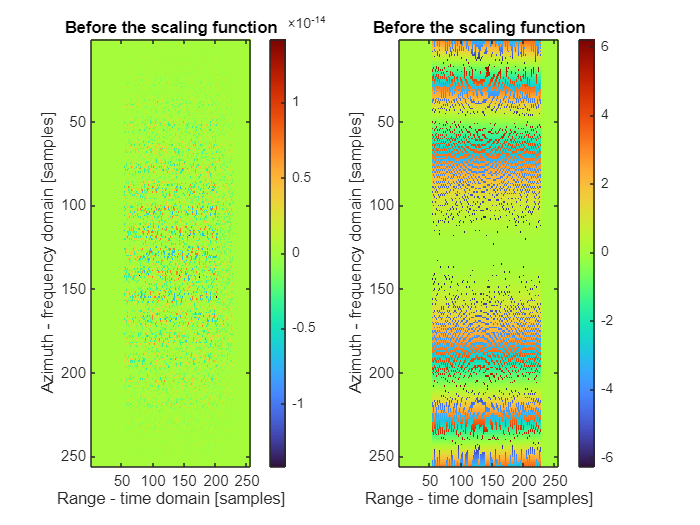

figure;
subplot(1,2,1);
imagesc(abs(range_Doppler_scaled_data)-abs(range_Doppler_data));
colormap('turbo');
colorbar;
xlabel('Range - time domain [samples]');
ylabel('Azimuth - frequency domain [samples]');
title('Before the scaling function');

subplot(1,2,2);
imagesc(angle(range_Doppler_scaled_data)-angle(range_Doppler_data));
colormap('turbo');
colorbar;
xlabel('Range - time domain [samples]');
ylabel('Azimuth - frequency domain [samples]');
title('Before the scaling function');

Em seguida, os dados escalonados são passados para o domínio da frequência bidimensional, aplicando uma FFT em range:

bi_frequency_data = complex(zeros(Naz,Nrg));
for i = 1:Naz
    bi_frequency_data(i,:) = fftshift(fft(range_Doppler_scaled_data(i,:)));
end

Agora, deve-se aplicar o filtro casado, realizar compressão secundária em range e RCMC grosseira. Na ordem, temos:

% Criação do suporte de frequência em range
freq_support_range = linspace(-Fr/2,Fr/2,Nrg);
% Computação do filtro casado em range
range_mf = get_range_mf(D,D_ref,Km,Tr,freq_support_range);
% PAREI AQUI ÀS 18:01 DE 27/11/2024. Rodrigo
% FALTA FAZER A CORREÇÃO SRC (OPCIONAL) E A CORREÇÃO GROSSEIRA (BULK). PARA
% FAZER ISTO, BASTA OLHAR A QUARTA EXPONENCIAL DA EQUAÇÃO (7.32) DE [1]

% continuando a partir daqui: (Gustavo)
R_ref = R0;

bulk = exp(1j*((4*pi*R_ref)/c).*((1./D)-(1/D_ref)).*freq_support_range); % conjugado da quarta exponencial

range_compressed = complex(zeros(Naz,Nrg));
for i = 1:Naz
    range_compressed(i,:) = bi_frequency_data(i,:) .* range_mf .* bulk .* kaiser(Nrg,0.5).';
end

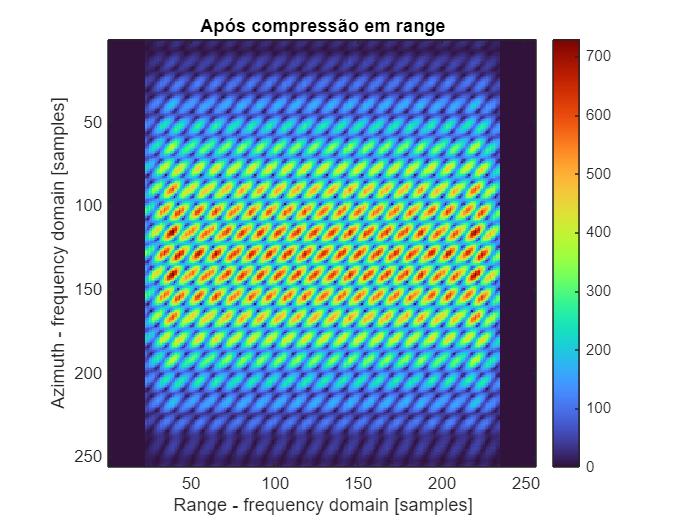

% Apresentação da imagem após compressão em range
figure;
imagesc(abs(range_compressed));
colormap('turbo');       
colorbar;
axis image;  
xlabel('Range - frequency domain [samples]');
ylabel('Azimuth - frequency domain [samples]');
title('Após compressão em range');

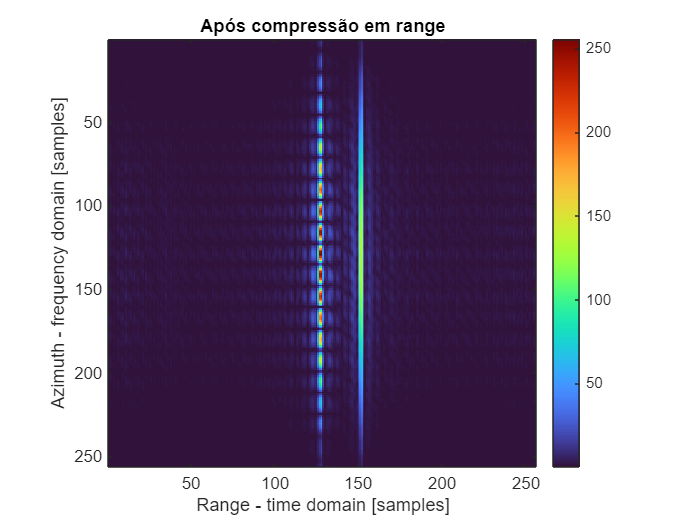

for i = 1:Naz
    range_compressed(i,:) = ifft(range_compressed(i,:));
end

% Apresentação da imagem após compressão em range
figure;
imagesc(abs(range_compressed));
colormap('turbo');       
colorbar;
axis image;  
xlabel('Range - time domain [samples]');
ylabel('Azimuth - frequency domain [samples]');
title('Após compressão em range');

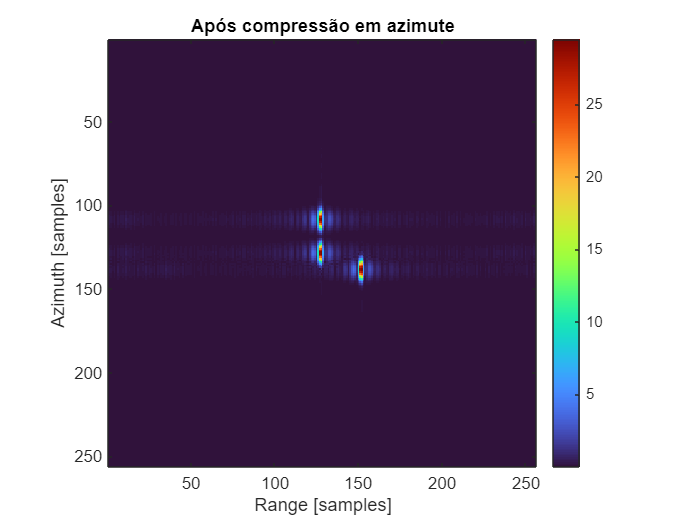

azimuth_mf = exp(1j*((4*pi*R0*f0.*D)./c));

res_phase_corr = exp(-1j*((4*pi*Km)./c^2).*(1-(D./D_ref).*((R0./D)-(R_ref./D)).^2));

azimuth_compressed = zeros(Naz,Nrg);
for i = 1:Naz
    azimuth_compressed(:,i) = range_compressed(:,i).* azimuth_mf.' .* res_phase_corr.' .* kaiser(Nrg,1.8);
end

compressed_data = zeros(Naz,Nrg);
for i = 1:Nrg
    compressed_data(:,i) = ifft(azimuth_compressed(:,i));
end

% Apresentação da imagem após compressão em azimute
figure;
imagesc(abs(compressed_data));
colormap('turbo');       
colorbar;
axis image;  
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Após compressão em azimute');

% Tentei completar os passos seguintes, mas pelas imagens tem algum erro no
% meio do caminho que não achei. (Gustavo) 27/11 23:40

### Funções usadas no código

function range_mf = get_range_mf(D,D_ref,Km,Tr,freq_support_range)
    % O SRC já está sendo feito na construção do filtro casado aqui.
    rect = double(abs(freq_support_range) <= ((Km*Tr)/2));
    range_mf = exp(1j.*((pi.*D)./(Km.*D_ref)).*(freq_support_range.^2)).*rect;
end

function s_sc = get_scaling_function(Km,D,D_ref,tau_support,Naz,Nrg)
    s_sc = complex(zeros(Naz,Nrg));
    for i = 1:Nrg
        s_sc(:,i) = exp(1j * Km .* ((D_ref./D) - 1)*(tau_support(i).^2));
    end
end

function f_eta_c = get_f_eta_c(Vr,lambda,R0,eta_c)
% A equação aproximada da frequência de centroide Doppler foi obtida 
% a partir da equação 8 da aula 08 do professor Dimas.
    Ka = get_Ka(Vr,lambda,R0);
    f_eta_c = -Ka*eta_c;
end

function D = get_D(Vr,c,f0,freq)
    % Esta função computa o parâmetro de migração em range.
    D = sqrt(1 - (c.*freq).^2 / (4*(Vr*f0)^2));
end

function Km = get_Km(Vr,c,f0,freq,Kr,R0,D)
    % Esta função computa a taxa FM modificada
    Km = Kr./(1-Kr*(c*R0*(freq.^2)./(2*(Vr^2)*(f0^3).*(D.^3))));
end

function Ka = get_Ka(Vr,lambda,R0)
%A equação aproximada de Ka foi obtida a
% partir da equação 5 da aula 08 do professor Dimas.
    Ka = (2*Vr^2)/(lambda*R0);
end

## Referências

[1] Cumming, I. G., & Wong, F. H. (2005). *Digital Processing of Synthetic Aperture Radar Data: Algorithms and Implementation*. Artech House.